clc
clear all
format long


%%%%%%Variable declaration%%%%%%%%%%%%
%-------------------------------------------%
F_f=0.5:0.5:1.5 %non-dimensional forcing frequency

F_f =    0.500000000000000   1.000000000000000   1.500000000000000


A=0.07; % non-dimensional forcing amplitude
omega_mat=2*pi*F_f %circular frequency

omega_mat =    3.141592653589793   6.283185307179586   9.424777960769379


phi=0; %initial phase
t1=0; % initial time
t_run=40; %final time


dt=1e-5; %time step
num_vor=100; %number of vortices shed;

for omega = omega_mat
    for j=1:num_vor
        
        tm=(t1):dt:(t1+t_run);
        for i=1:length(tm)
            tt=tm(i+1)-t1; 
            gam(i)=tt*(A^2/4+1/2)-A^2*(sin(2*omega*tm(i+1)+2*phi)-sin(2*omega*t1+2*phi))/(8*omega)+...
                A*(cos(omega*t1+phi)-cos(omega*tm(i+1)+phi))/omega; %Gamma_m
            gam_c(i)=0.5*(1+A*sin(omega*tm(i+1)+phi)); %threshold circulation Gamma_sep
            
            if gam(i)>=gam_c(i)
                gam(i+1)=0;
                tf(j)=tt; %Shedding time period
                break
            end
        end
        
        clear gam gam_c
        t1=tm(i+1);  %t1=t2 condition 
        j;
    end
    p = (omega/(2*pi))*ones(1, length(tf(50:end)));
    omega/(2*pi)
    %if (omega/(2*pi)) == tf(end)
     %   plot(p(end), 1./tf(end),"ro",'MarkerSize',4)
      %  disp("ha")
    %else
    plot(p, 1./tf(50:end), "color",'#A2142F',"LineWidth",3, "Marker",".", "MarkerSize", 17)
    %end
    hold on
    clear p
end

ans =    0.500000000000000


ans =      1


ans =    1.500000000000000


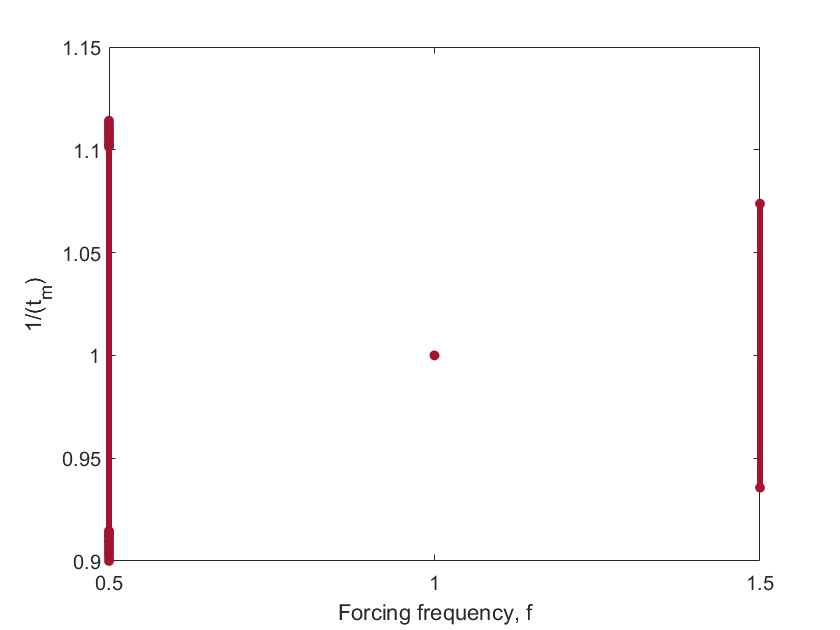

hold off
xlabel("Forcing frequency, f")
ylabel("1/(t_m)")